# Conductance Based LIF Model

% Conductance Parameters 

Ek = -80e-3; % Potassium reversal potential (V)
gref = zeros(size(tvec)); % Conductance of K channels (S)
gref(1) = 0; % Set initial conductance to zero
gtau = 0.2e-3; % Time constant for conductance decay (s)
deltag = 2e-6; % Change in conductance due to spike (S)

% Create voltge vector
vth3 = zeros(size(tvec));      % Voltage threshold (V)
vth3(1) = Vth;                 % Set first element to Vth
fr_3 = zeros(size(Iapp));      % Firing rate vector
Vvec3 = zeros(size(tvec));     % Membrane potential vector
Vvec3(1) = El;                 % Set initial membrane potential to leaky EP
mean_V3 = zeros(size(Iapp));   % Mean membrane potential
pltV3 = zeros(2,length(tvec)); % Voltage vs time for Iapp = 220pA and 600pA

## Simulate Firing

% Loop through the values of Iapp
for k = 1:length(Iapp)
    spiket3 = zeros(size(tvec)); % Spike times
    % Loop through time points in tvec
     for i = 2:length(tvec)
        % Calculate the derivative of membrane potential
        dVdt = 1/Cm * ((El - Vvec3(i-1))/Rm + gref(i-1)*(Ek-Vvec3(i-1)) + Iapp(k));
        % Update membrane potential
        Vvec3(i) = Vvec3(i-1) + dVdt * dt;
        % Calculate the derivative of threshold voltage after spike
        dVthdt = (Vth - vth3(i-1))/vtau;
        % Update threshold voltage
        vth3(i) = vth3(i-1) + dVthdt * dt;
        % Update conductance
        gref(i) = gref(i-1) - (gref(i-1)/gtau) * dt;
        % If threshold voltage is reached, spike occurs
        if Vvec3(i) > vth3(i)
            spiket3(i) = 1;
            vth3(i) = vth_max;
            gref(i) = gref(i) + deltag;
        end
     end

    % Set membrane potential above threshold to Vpeak
    spikecount3 = find(spiket3 == 1);
    for ind = spikecount3
    Vvec3(ind) = Vpeak;
    end
    
    % Calculate mean firing rate
    mean_V3(k) = mean(Vvec3);
    fr_3(k) = length(spikecount3)/tmax;
    
    % Store membrane potential vs time for Iapp = 220pA and 600pA
    if k == 13 % Iapp = 220pA
    pltV3(1,:) = Vvec3;
    elseif k == 51 % Iapp = 600pA
    pltV3(2,:) = Vvec3;
    end
end

## Plot Simulated Voltage Trace

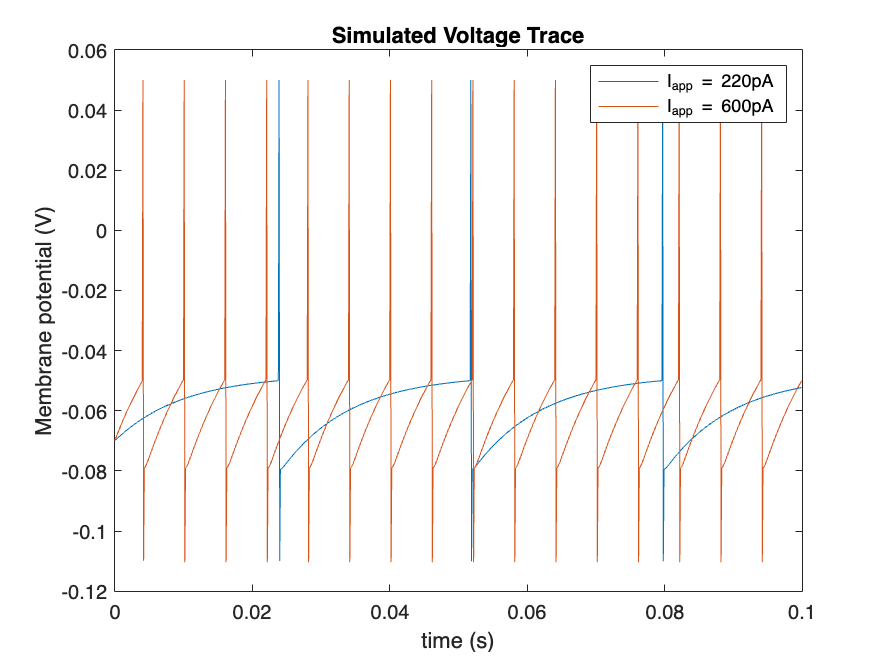

figure;
plot(tvec(:,1:1000), pltV3(1,1:1000), tvec(:,1:1000), pltV3(2,1:1000))
title('Simulated Voltage Trace')
xlabel('time (s)'), ylabel('Membrane potential (V)')
legend('I_{app} = 220pA', 'I_{app} = 600pA')